## **Clean up variables and RoadRunner**

% Check if a variable called "rrApp" exists in workspace
if exist("rrApp", "var") 
     % Check if it's actually a RoadRunner object (not something else)
    if class(rrApp) == "roadrunner"
        rrApp.close(); % Close the RoadRunner window properly
    end
end

% Check if rrSim exists (the simulation connection object)
if exist("rrSim", "var")
    delete(rrSim);  % Disconnect and delete the simulation object
end

close all;
clear;
setenv("NO_PROXY", "localhost");  % Tell MATLAB not to use a proxy 
                                  % server for localhost connections
                                  % (fixes connection issues between
                                  % MATLAB and RoadRunner)



## Launch RoadRunner from Matlab 

%Launch RoadRunner 
rrProj = "C:\Users\user\OneDrive\Documents\Test 1";
rrApp = roadrunner(rrProj);

%Check launch status 
status(rrApp)

ans = struct with fields:
     Project: [1×1 struct]
       Scene: [1×1 struct]
    Scenario: []



%Open Scene
openScene(rrApp,"C:\Users\user\OneDrive\Documents\Test 1\Scenes\UNM_FrontJunct-V2.rrscene");

%Open Scenario 
openScenario(rrApp,"C:\Users\user\OneDrive\Documents\Test 1\Scenarios\UNM_Eg-Test2.rrscenario");

%Create scenario simulation objs to manage simulations 
rrSim = createSimulation(rrApp);

Connection status: 1
Connected to RoadRunner Scenario server on localhost:60729, with client id {ad94ba51-ac8c-41a6-9c94-605407eb50ad}


%Enable data logging 
set(rrSim,Logging="on")

%Set scenario to run at step size of 0.1s = Frame rate of simulation  
Ts = 0.1;
rrSim.set("StepSize", Ts);

% Setup everything before simulation starts 
UNM_Setup(rrApp,rrSim);

Loading UNM bus objects...
  [OK] BusActorRuntime loaded
  [OK] BusVehicleRuntime loaded
  [OK] BusRuntimeTurnConfiguration loaded
  [OK] BusBulbConfiguration loaded
  [OK] BusSignalConfiguration loaded
  [OK] BusSignalHead loaded
  [OK] BusTrafficSignalRuntime loaded

All UNM bus objects loaded successfully!
You can now open UNM_TrafficSignalFollower.slx

Loading UNM bus objects...
  [OK] BusActorRuntime loaded
  [OK] BusVehicleRuntime loaded
  [OK] BusRuntimeTurnConfiguration loaded
  [OK] BusBulbConfiguration loaded
  [OK] BusSignalConfiguration loaded
  [OK] BusSignalHead loaded
  [OK] BusTrafficSignalRuntime loaded

All UNM bus objects loaded successfully!
You can now open UNM_TrafficSignalFollower.slx




% Open the Simulink model
model_name = "C:\Users\user\OneDrive\Documents\MATLAB\Summer_Intern\Simulink\UNM_TrafficSignalFollower.slx";
open_system(model_name)




## Reinforcement Learning

% Observation
obsInfo = rlNumericSpec([9 1],...
   'LowerLimit', [0; 0; 0; 0; 0; 0;   0; -20;  0], ...
   'UpperLimit', [1; 1; 1; 1; 1; 1; 100;  20; 15]);
obsInfo.Name = "observations";
obsInfo.Description = "relative distance,relative velocity and ego velocity";

% Action
actInfo = rlNumericSpec([1 1], ...
    LowerLimit=-3,UpperLimit=2);
actInfo.Name = "acceleration";

% Environment
model_name = bdroot;
agentBlockPath = find_system(bdroot, 'MaskType', 'RL Agent');
agentBlockPath = agentBlockPath{1};
env = rlSimulinkEnv(model_name, agentBlockPath, obsInfo, actInfo); 
env.UseFastRestart = "off";   

% Start with randomized lead-vehicle speed or signal phase timing
env.ResetFcn = @(in) localResetFcn(in);

function in = localResetFcn(in)
    randSpeed = 5 + 5*rand;   % example: randomize lead vehicle's initial speed
    in = setVariable(in, 'LeadInitialSpeed', randSpeed);
end

## Build actor and critic networks, create RL agent

obsDim = obsInfo.Dimension(1);   % 9
actDim = actInfo.Dimension(1);   % 1

% Critic (estimates value of a state)
criticNet = [
    featureInputLayer(obsDim, 'Name', 'obsIn')
    fullyConnectedLayer(64, 'Name', 'fc1')
    reluLayer('Name', 'relu1')
    fullyConnectedLayer(64, 'Name', 'fc2')
    reluLayer('Name', 'relu2')
    fullyConnectedLayer(1, 'Name', 'value')
];
critic = rlValueFunction(criticNet, obsInfo);

% Actor (outputs mean and std for a Gaussian policy over accelCmd)
commonPath = [
    featureInputLayer(obsDim, 'Name', 'obsIn')
    fullyConnectedLayer(64, 'Name', 'fc1')
    reluLayer('Name', 'relu1')
    fullyConnectedLayer(64, 'Name', 'fc2')
    reluLayer('Name', 'relu2')
];
meanPath = [
    fullyConnectedLayer(actDim, 'Name', 'meanOut')
    tanhLayer('Name', 'tanh')
    scalingLayer('Name', 'scaledMean', 'Scale', 2.5, 'Bias', -0.5)  % maps to [-3, 2]
];
stdPath = [
    fullyConnectedLayer(actDim, 'Name', 'stdOut')
    softplusLayer('Name', 'std')
];

net = layerGraph(commonPath);
net = addLayers(net, meanPath);
net = addLayers(net, stdPath);
net = connectLayers(net, 'relu2', 'meanOut');
net = connectLayers(net, 'relu2', 'stdOut');

actor = rlContinuousGaussianActor(net, obsInfo, actInfo, ...
    'ActionMeanOutputNames', 'scaledMean', ...
    'ActionStandardDeviationOutputNames', 'std', ...
    'ObservationInputNames', 'obsIn');

agent = rlPPOAgent(actor, critic);
agent.SampleTime = 0.1;   % must match your model's Ts

## Training

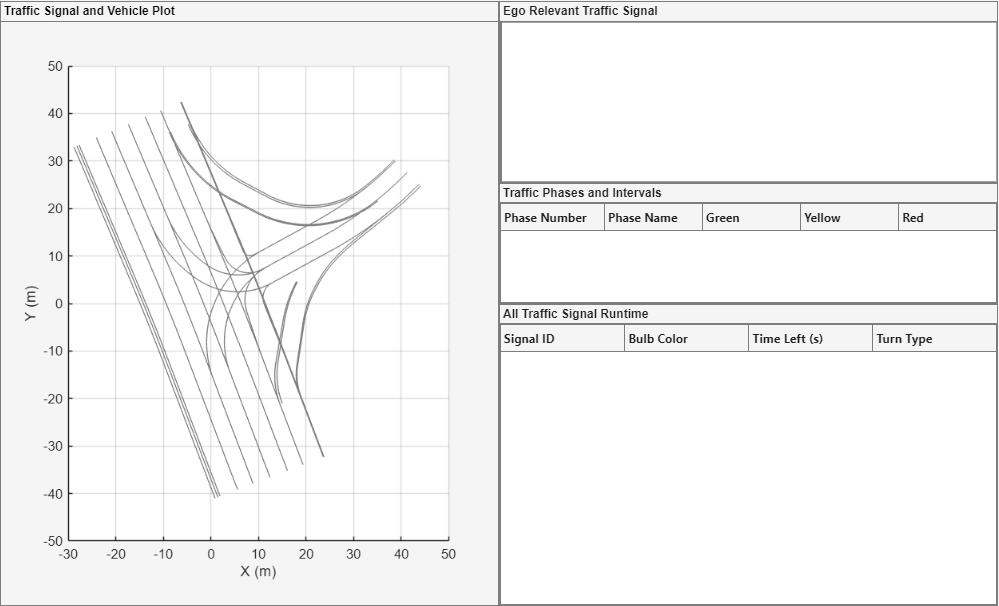

Error using rl.internal.train.PPOTrainer/run_internal_/nestedRunEpisode (line 351)
An error occurred while running the simulation for model 'UNM_TrafficSignalFollower' with the following RL agent blocks:
 	UNM_TrafficSignalFollower/RL Agent

Error in rl.internal.train.PPOTrainer/run_internal_ (<a href="ma

trainOpts = rlTrainingOptions(...
    'MaxEpisodes', 1, ...
    'MaxStepsPerEpisode', 30, ...
    'StopTrainingCriteria', 'AverageReward', ...
    'StopTrainingValue', -5, ...   % tune once you see real reward magnitudes
    'ScoreAveragingWindowLength', 20, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

trainingStats = train(agent, env, trainOpts);

## Start Simulation

% Start simulation
set(rrSim, SimulationCommand="Start")

% Wait until RoadRunner Scenario simulation is finished
while strcmp(rrSim.get("SimulationStatus"),"Running")
  pause(1)
end

% After simulation stops
rrLog = rrSim.get("SimulationLog");

% Get velocity of actor 1
velocityLog = get(rrLog, 'Velocity', 'ActorID', 1);
timeLog = [velocityLog.Time];

% Calculate speed magnitude at each timestep
speedValues = arrayfun(@(x) norm(x.Velocity), velocityLog);

% Plot
figure
plot(timeLog, speedValues);
xlabel('Time (s)');
ylabel('Speed (m/s)');
title('Ego Vehicle Speed Profile');
grid on;